[status,sheets] = xlsfinfo('NguyenDHWPart2')%shows that 3 sheets exist

status = 'Microsoft Excel Spreadsheet'

sheets = 1×1 cell array
    {'Sheet1'}


% the command to read the data
[A,names,raw] =xlsread('NguyenDHWPart2',1);% reads the first sheet only
LN=length(names) % number of columns with names

LN = 0

A % data only

A =     0.6265
    0.9003
    1.5174
    1.6848
    1.0044
    0.6111
    1.0738
    0.7023
    2.7150
    0.9658


names % headers


names =

  0×0 empty cell array



raw % headers and data

raw = 110×1 cell array
    {[0.6265]}
    {[0.9003]}
    {[1.5174]}
    {[1.6848]}
    {[1.0044]}
    {[0.6111]}
    {[1.0738]}
    {[0.7023]}
    {[2.7150]}
    {[0.9658]}
    {[1.8268]}
    {[0.5647]}
    {[1.0221]}
    {[1.9608]}
    {[1.4774]}
    {[0.9788]}


data = A(:,1)% get the first colum data

data =     0.6265
    0.9003
    1.5174
    1.6848
    1.0044
    0.6111
    1.0738
    0.7023
    2.7150
    0.9658


% x and y are of different lengths. Because of this, y contains NaN
 % suppress the NaN
% plot the histograms
x = data(1:60,:)

x =     0.6265
    0.9003
    1.5174
    1.6848
    1.0044
    0.6111
    1.0738
    0.7023
    2.7150
    0.9658



%figure,histogram(x,8,'normalization','pdf','FaceColor','g')
%hold on
y= data(61:110)

y =     5.8181
    2.4876
    2.8938
    2.1823
    2.3053
    1.0142
    1.8055
    1.3264
    3.0247
    6.0584



%hold on
%histogram(y,8,'normalization','pdf','FaceColor','y')
%hold on


%AUC graph
N0=length(x);
N1=length(y);
resp=[zeros(N0,1);ones(N1,1)]; % labels
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,data,1);
figure,plot(pf,pd)
hold on
dist=sqrt( (0-pf).^2 + (1-pd).^2)

dist =     1.0000
    0.9800
    0.9600
    0.9400
    0.9200
    0.9000
    0.8800
    0.8600
    0.8400
    0.8200


opt = find(dist == min(dist))

opt = 45

plot(pf(opt),pd(opt),'o', 'MarkerFaceColor', 'g')
plot(2/60,18/25, 'o', 'MarkerFaceColor', 'r')

m=linspace(0,1);
n=m;
plot(m, n, 'r', 'linewidth', 1.5)

performance=(mean(y)-mean(x))/(sqrt(var(x)+var(y)))

performance = 1.2792

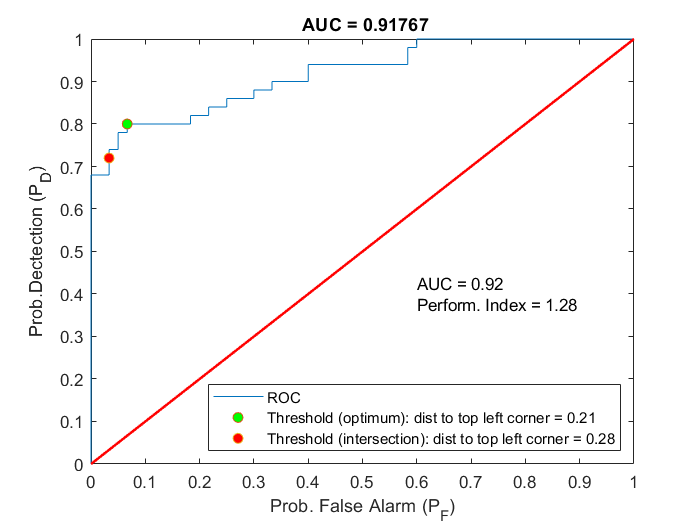


txt = {'AUC = 0.92', 'Perform. Index = 1.28'};
text(0.6,0.4,txt)
xlabel('Prob. False Alarm (P_F)'),ylabel('Prob.Dectection (P_D)'),title([' AUC = ',num2str(AUC)])
legend('ROC','Threshold (optimum): dist to top left corner = 0.21','Threshold (intersection): dist to top left corner = 0.28','Location','southeast')
hold off

%next
xx=0:0.01:1.2*max(x);% get the x-coordinates to get the ksdensity
fx1=ksdensity(x,xx);

idmax1=find(fx1==max(fx1))

idmax1 = 92

threshold1 = round(median(idmax1))

threshold1 = 92

plot(xx,fx1,'-r','linewidth',1.5)
hold on
yy=0:0.01:1.2*max(y);% get the x-coordinates to get the ksdensity
fx2=ksdensity(y,yy);

idmax2=find(fx2==max(fx2))

idmax2 = 385

threshold2 = round(median(idmax2))

threshold2 = 385

plot(yy,fx2,'--b','linewidth',1.5)
xlabel('input data'),ylabel('estimated densities'), title('Threshold (optimum): thr = 2.19')
% create a title from the header information directly
xxfill=xx(219:326)

xxfill =     2.1800    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900    2.5000    2.5100    2.5200    2.5300    2.5400    2.5500    2.5600    2.5700    2.5800    2.5900    2.6000    2.6100    2.6200    2.6300    2.6400    2.6500    2.6600    2.6700


fx1fill=fx1(219:326)

fx1fill =     0.2624    0.2582    0.2539    0.2496    0.2453    0.2410    0.2367    0.2325    0.2282    0.2240    0.2198    0.2156    0.2114    0.2073    0.2032    0.1991    0.1951    0.1911    0.1871    0.1832    0.1793    0.1755    0.1717    0.1679    0.1642    0.1606    0.1570    0.1535    0.1500    0.1465    0.1431    0.1398    0.1365    0.1333    0.1301    0.1270    0.1239    0.1209    0.1179    0.1150    0.1121    0.1093    0.1065    0.1037    0.1011    0.0984    0.0958    0.0933    0.0907    0.0883


xxfill(1)=2.19

xxfill =     2.1900    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900    2.5000    2.5100    2.5200    2.5300    2.5400    2.5500    2.5600    2.5700    2.5800    2.5900    2.6000    2.6100    2.6200    2.6300    2.6400    2.6500    2.6600    2.6700


fx1fill(1)=0

fx1fill =          0    0.2582    0.2539    0.2496    0.2453    0.2410    0.2367    0.2325    0.2282    0.2240    0.2198    0.2156    0.2114    0.2073    0.2032    0.1991    0.1951    0.1911    0.1871    0.1832    0.1793    0.1755    0.1717    0.1679    0.1642    0.1606    0.1570    0.1535    0.1500    0.1465    0.1431    0.1398    0.1365    0.1333    0.1301    0.1270    0.1239    0.1209    0.1179    0.1150    0.1121    0.1093    0.1065    0.1037    0.1011    0.0984    0.0958    0.0933    0.0907    0.0883


xxfill(326)=max(xx)

xxfill =     2.1900    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900    2.5000    2.5100    2.5200    2.5300    2.5400    2.5500    2.5600    2.5700    2.5800    2.5900    2.6000    2.6100    2.6200    2.6300    2.6400    2.6500    2.6600    2.6700


fx1fill(326)=0

fx1fill =          0    0.2582    0.2539    0.2496    0.2453    0.2410    0.2367    0.2325    0.2282    0.2240    0.2198    0.2156    0.2114    0.2073    0.2032    0.1991    0.1951    0.1911    0.1871    0.1832    0.1793    0.1755    0.1717    0.1679    0.1642    0.1606    0.1570    0.1535    0.1500    0.1465    0.1431    0.1398    0.1365    0.1333    0.1301    0.1270    0.1239    0.1209    0.1179    0.1150    0.1121    0.1093    0.1065    0.1037    0.1011    0.0984    0.0958    0.0933    0.0907    0.0883



yyfill=yy(1:221)

yyfill =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


fx2fill=fx2(1:221)

fx2fill =     0.0350    0.0355    0.0360    0.0365    0.0369    0.0374    0.0379    0.0384    0.0389    0.0394    0.0399    0.0404    0.0409    0.0415    0.0420    0.0425    0.0430    0.0436    0.0441    0.0446    0.0452    0.0457    0.0463    0.0468    0.0474    0.0479    0.0485    0.0490    0.0496    0.0502    0.0507    0.0513    0.0519    0.0525    0.0530    0.0536    0.0542    0.0548    0.0554    0.0560    0.0566    0.0572    0.0578    0.0584    0.0590    0.0596    0.0602    0.0609    0.0615    0.0621


yyfill(221)=2.19

yyfill =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


fx2fill(1)=0

fx2fill =          0    0.0355    0.0360    0.0365    0.0369    0.0374    0.0379    0.0384    0.0389    0.0394    0.0399    0.0404    0.0409    0.0415    0.0420    0.0425    0.0430    0.0436    0.0441    0.0446    0.0452    0.0457    0.0463    0.0468    0.0474    0.0479    0.0485    0.0490    0.0496    0.0502    0.0507    0.0513    0.0519    0.0525    0.0530    0.0536    0.0542    0.0548    0.0554    0.0560    0.0566    0.0572    0.0578    0.0584    0.0590    0.0596    0.0602    0.0609    0.0615    0.0621


yyfill(1)=0

yyfill =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


fx2fill(221)=0

fx2fill =          0    0.0355    0.0360    0.0365    0.0369    0.0374    0.0379    0.0384    0.0389    0.0394    0.0399    0.0404    0.0409    0.0415    0.0420    0.0425    0.0430    0.0436    0.0441    0.0446    0.0452    0.0457    0.0463    0.0468    0.0474    0.0479    0.0485    0.0490    0.0496    0.0502    0.0507    0.0513    0.0519    0.0525    0.0530    0.0536    0.0542    0.0548    0.0554    0.0560    0.0566    0.0572    0.0578    0.0584    0.0590    0.0596    0.0602    0.0609    0.0615    0.0621



fill(xxfill,fx1fill,'y')
fill(yyfill,fx2fill,'g')

txt2 = {'P_M'}

txt2 = 1×1 cell array
    {'P_M'}


text(1,0.03,txt2)

txt3 = {'P_F'}

txt3 = 1×1 cell array
    {'P_F'}


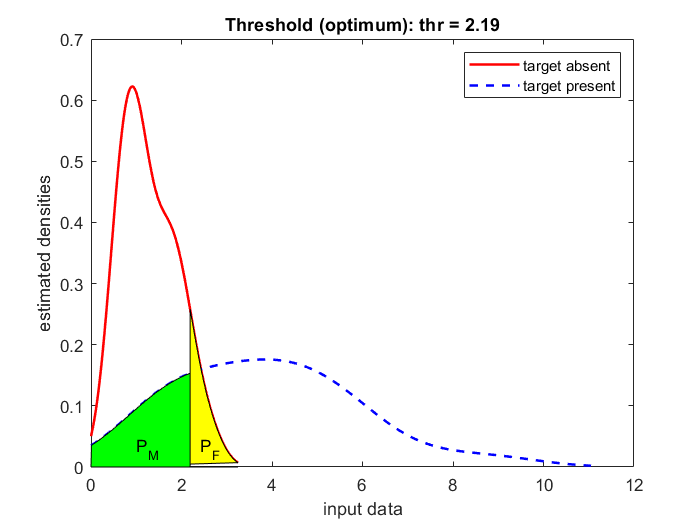

text(2.4, 0.03, txt3)
legend('target absent','target present');
hold off